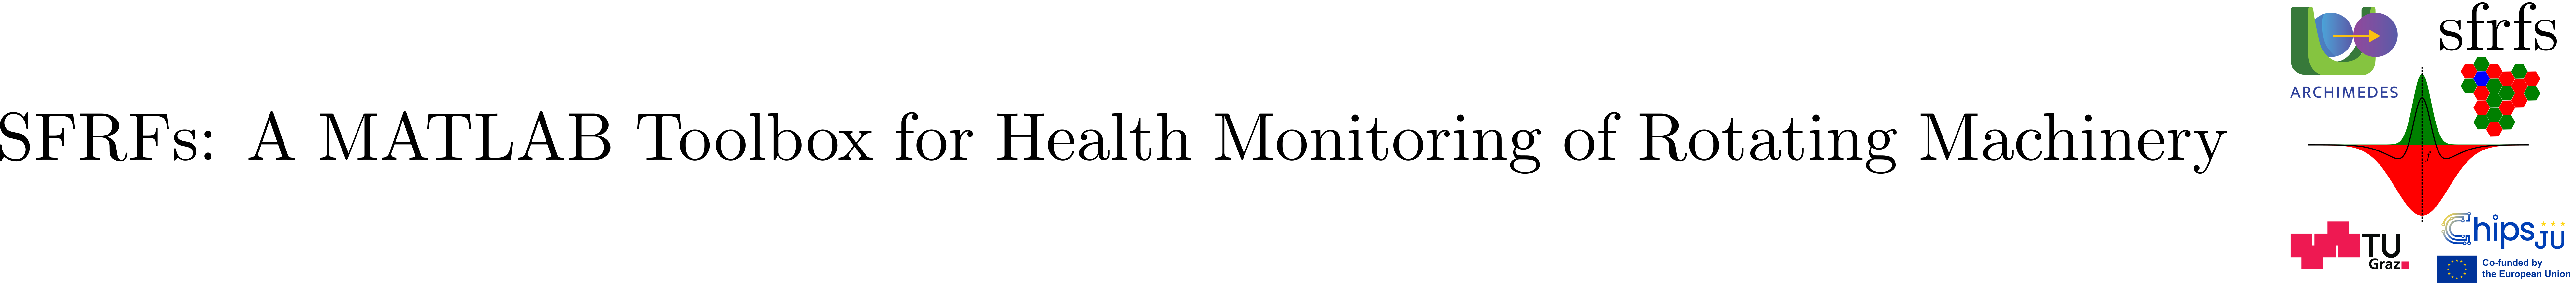

# EnsembleDatastoreRegistry

## Summary

The `EnsembleDatastoreRegistry` class serves as the central registry for managing `fileEnsembleDatastore` objects. It enables the registration, deregistration, and controlled reconfiguration of ensemble descriptors in a persistent manner.

**Key features**:

- Static factory and registry for managing `fileEnsembleDatastore` instances in the context of the SFRFs toolbox.

- Robust and persistent storage with name based lookup for reproducible retrieval.

- Support for safe replacement, update, reconfiguration, and removal of ensembles.

- Integration with the SFRFsLogger subsystem for traceability and debugging.

- Centralized handling of ensemble definition metadata to ensure transparent and reproducible ensemble management.

## Description

`EnsembleDatastoreRegistry` is a static, centralized registry that provides persistent and transparent management of named `fileEnsembleDatastore` objects within the SFRFs framework. Since `fileEnsembleDatastore` instances do not preserve metadata across MATLAB sessions, the registry supplies a durable bookkeeping layer that ensures ensemble definitions remain consistent to changes and reproducible throughout the processing pipeline.

The registry maintains an internal persistent dictionary that maps ensemble names to their corresponding datastore objects. This dictionary is stored both in memory and on disk, allowing deterministic reconstruction of all registered ensembles through name based lookup. The class supports safe addition, retrieval, reconfiguration, and removal of ensembles while ensuring that updates to their metadata are persisted immediately. All operations integrate with the SFRFs logging subsystem, providing detailed traceability and auditability.

`EnsembleDatastoreRegistry` also offers controlled reconfiguration functionalities. Users may redefine data variables, independent variables, condition variables, or selected variables for an ensemble, after which the datastore is reset and the updated metadata is persisted. 

### Public  methods (static)

## Example

#### Mock ensemble

The EnsembleMock unit test utility class creates a temporary folder and saves ensemble files with random data. For the example we create two ensembles.

% Values from Wang et al.'s XJTU-SY datases.
% Create the snapshot parameters
sp = ParametersSnapshot(...
    'samplingFrequency', 25600, ...
    'duration', 1.28, ...
    'stride', 60);
% Define speeds and loads of the test
speeds = [35; 37.5; 40];
loads  = [12; 11; 10];

% Initialize and prepare ensemble 1
ensemble1 = EnsembleMock( ...
    'numMembers', 7, ...
    'nSamples', sp.getTotalSamples(), ...
    'speeds', speeds, ...
    'loads', loads);

% Initialize and prepare ensemble 1
ensemble2 = EnsembleMock( ...
    'numMembers', 11, ...
    'nSamples', sp.getTotalSamples(), ...
    'speeds', speeds, ...
    'loads', loads);

% Creates temp folder and saves ensemble1 files with random data
ensemble1.prepare();        
% Creates temp folder and saves ensemble2 files with random data
ensemble2.prepare();  

#### Registering ensembles

To register the ensembles we use the method `addEnsemble`.

% Register the ensemble in the factory with a name
EnsembleDatastoreRegistry.addEnsemble(...
    name = "ensemble-random-data-1", datastore = ensemble1.fileEnsembleDS);
EnsembleDatastoreRegistry.addEnsemble(...
    name = "ensemble-random-data-2", datastore = ensemble2.fileEnsembleDS);

#### Querying for all registered ensembles

We use the method `getAllEnsembleNames `to obtain the list of registered ensembles.

% Obtaining all fileEnsembleDatastore entries in the registry
disp(EnsembleDatastoreRegistry.getAllEnsembleNames())

    "ensemble-random-data-1"
    "ensemble-random-data-2"



#### Retrieving an ensemble handle

We can retrieve the handle using the method `getEnsemble and the name` with which the `fileEnsembleDatastore` was previously registered.

% Obtaining instance of first ensemble
firstEnsemble = EnsembleDatastoreRegistry.getEnsemble( ...
    "ensemble-random-data-1")

firstEnsemble =   fileEnsembleDatastore with properties:

                 ReadFcn: @EnsembleMock.readMember
        WriteToMemberFcn: @EnsembleMock.writeMember
           DataVariables: [2×1 string]
    IndependentVariables: "SnapshotIndex"
      ConditionVariables: [2×1 string]
       SelectedVariables: [5×1 string]
                ReadSize: 1
              NumMembers: 7
          LastMemberRead: [0×0 string]
                   Files: [7×1 string]


#### Checking regitration

To check if an ensemble is in the registry we use the method `hasEnsemble.`

% Obtaining instance of first ensemble
name = "ensemble-random-data-2";
inRegistry = EnsembleDatastoreRegistry.hasEnsemble(name);
if inRegistry
    disp(name+" is in the registry.");
else
    disp(name+" is not in the registry.");
end

ensemble-random-data-2 is in the registry.


#### Reconfiguring ensembles

We will add a column with the mean values and reconfigure the ensemble to reflect the changes.

1. Obtain ensemble handle.

% Obtaining the second ensemble
name = "ensemble-random-data-2";
ensemble = EnsembleDatastoreRegistry.getEnsemble(name)

ensemble =   fileEnsembleDatastore with properties:

                 ReadFcn: @EnsembleMock.readMember
        WriteToMemberFcn: @EnsembleMock.writeMember
           DataVariables: [2×1 string]
    IndependentVariables: "SnapshotIndex"
      ConditionVariables: [2×1 string]
       SelectedVariables: [5×1 string]
                ReadSize: 1
              NumMembers: 11
          LastMemberRead: [0×0 string]
                   Files: [11×1 string]


2. Inspect the variables holding the raw data

disp(ensemble.DataVariables);

    "HorizontalAcceleration"
    "VerticalAcceleration"



2. Compute a new column with the mean value of vibrations.

% Compute function is the mean value of raw signals
meanFcn = @(x) mean(x);

% Source column is HorizontalAcceleration
sourceColumn = "HorizontalAcceleration";

% The new column name
targetColumn = "MeanHorizontalAcceleration";

% Use the function to add a mean column
addComputedColumnToEnsemble(ensemble, sourceColumn, targetColumn, meanFcn);

3. Reconfigure the ensemble to include this new column.

% redefine the variables
dataVariables = [
    ensemble.DataVariables(:);
    targetColumn];
selectedVariables = [
    ensemble.IndependentVariables(:); 
    ensemble.DataVariables(:)];

% apply reconfiguration and get the handle
ensemble = EnsembleDatastoreRegistry.reconfigureEnsemble(...
    name=name, ...
    DataVariables=dataVariables,...
    SelectedVariables=selectedVariables)

ensemble =   fileEnsembleDatastore with properties:

                 ReadFcn: @EnsembleMock.readMember
        WriteToMemberFcn: @EnsembleMock.writeMember
           DataVariables: [4×1 string]
    IndependentVariables: "SnapshotIndex"
      ConditionVariables: [2×1 string]
       SelectedVariables: [4×1 string]
                ReadSize: 1
              NumMembers: 11
          LastMemberRead: [0×0 string]
                   Files: [11×1 string]


4.  Inspect computation

tbl = read(ensemble);
% Display the first few rows of the updated table
disp(head(tbl));

    SnapshotIndex    HorizontalAcceleration    VerticalAcceleration    MeanHorizontalAcceleration
    _____________    ______________________    ____________________    __________________________

          1             {32768×1 double}         {32768×1 double}               -0.013913        
          2             {32768×1 double}         {32768×1 double}              -0.0015735        
          3             {32768×1 double}         {32768×1 double}             -0.00097758        
          4             {32768×1 double}         {32768×1 double}              0.00035633        
          5             {32768×1 double}         {32768×1 double}             -0.00043677        



#### Deregistering ensembles

To delete an entry from the registry we use `removeEnsemble`.

% Removing first ensemble from registry
EnsembleDatastoreRegistry.removeEnsemble("ensemble-random-data-1");
% Check it is no longer in the registry
EnsembleDatastoreRegistry.getAllEnsembleNames()

ans = "ensemble-random-data-2"

#### Factory reset

To delete all entries you can use the method `factoryReset`. To perform the reset uncomment the command.

% Uncomment only if info in registry is not important!
%EnsembleDatastoreRegistry.factoryReset();
% empty registry
EnsembleDatastoreRegistry.getAllEnsembleNames()

## API documentation

### MATLAB help

help EnsembleDatastoreRegistry


ans = 

  0×1 empty string array



% Obtain help for specific functions, for example: 
help EnsembleDatastoreRegistry.addEnsemble

### MATLAB documentation

doc EnsembleDatastoreRegistry

  EnsembleDatastoreRegistry
    Static factory for registering, retrieving, reconfiguring, and
    managing fileEnsembleDatastore objects. Supports persistence,
    logging, and ensures that ensembles are globally accessible
    across MATLAB sessions.
 
    This class is sealed and provides only static methods; it does
    not need to be instantiated.
 
    Features:
      - Register new ensembles with addEnsemble
      - Retrieve ensembles by name with getEnsemble
      - Check existence with hasEnsemble
      - List all registered ensemble names with getAllEnsembleNames
      - Reconfigure ensemble variables with reconfigureEnsemble
      - Remove individual ensembles with removeEnsemble
      - Reset all registered ensembles with factoryReset
 
    All registered ensembles are persisted to a MAT-file in the
    user preferences directory and loaded automatically when needed.
 
    Usage:
        % Add a new ensemble
        EnsembleDatastoreRegistry.addEnsemble( ...
            nam

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Source code

Source code available in [EnsembleDatastoreRegistry](matlab:open('../../EnsembleDatastoreRegistry.m')).

## Test

Unit testing of the class is implemented in [TestEnsembleDatastoreRegistry](matlab:open('../../../tests/TestEnsembleDatastoreRegistry.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestEnsembleDatastoreRegistry');

  addEnsemble Register a new fileEnsembleDatastore
 
    EnsembleDatastoreRegistry.addEnsemble(Name, Datastore)
    registers a new ensemble with the factory. If an ensemble
    with the same name already exists, it will be overwritten
    and a log message is issued.
 
    Inputs (as Name-Value pairs):
        'name'      - Text scalar specifying the ensemble name.
        'datastore' - A fileEnsembleDatastore object to register.
 
    The method persists the updated registry to disk and updates
    the in-memory map, making the ensemble available for
    retrieval in the current and future MATLAB sessions.
 
    Example:
        ds = fileEnsembleDatastore(...); % construct datastore
        EnsembleDatastoreRegistry.addEnsemble( ...
            name = "myEnsemble", ...
            datastore = ds);
 
    See also: getEnsemble, reconfigureEnsemble, removeEnsemble,
    factoryReset



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

## Auxiliary functions

### `Compute new columns`

function addComputedColumnToEnsemble(...

Running TestEnsembleDatastoreRegistry
.....
Done TestEnsembleDatastoreRegistry
__________



    ensemble, sourceColumn, resultColumn, computeFcn)
% Adds a computed column to an ensemble, applying computeFcn row-wise

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestEnsembleDatastoreRegistry/testAddAndRetrieveEnsemble                         | Passed
TestEnsembleDatastoreRegistry/testGetAllNames                                    | Passed
TestEnsembleDatastoreRegistry/testReconfigureAndReset                            | Passed
TestEnsembleDatastoreRegistry/testNotFoundException                              | Passed
TestEnsembleDatastoreRegistry/testRemove                                         | Passed



%
% ensemble     - fileEnsembleDatastore or compatible object
% sourceColumn - name of the column with double arrays
% resultColumn - name for the new computed column
% computeFcn   - function handle to apply to each row's array

    % Ensure the result column is listed
    if ~ismember(resultColumn, ensemble.DataVariables)
        ensemble.DataVariables = ...
            [ensemble.DataVariables; string(resultColumn)];
    end

    reset(ensemble)
    while hasdata(ensemble)
        data = read(ensemble);      
        nRows = height(data);
        val = zeros(nRows,1);     

        % Compute row-wise
        for r = 1:nRows
            val(r) = computeFcn(data.(sourceColumn){r});
        end

        writeToLastMemberRead(ensemble, resultColumn, val);
    end

    reset(ensemble)
end

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).